Définition des constantes

G=6.6743*10^-11;
Mt=5.972*10^24;
ms=2164;
Rt=6371000;
h0=693000;

PARTIE 1

Definition des valeurs variables et simulation

v0=6000;
sim Sim_partie1.slx;
x1=ans.x;
y1=ans.y;
z1=ans.z;

v0=9000;
sim Sim_partie1.slx;
x2=ans.x;
y2=ans.y;
z2=ans.z;

v0=11000;
sim Sim_partie1.slx;
x3=ans.x;
y3=ans.y;
z3=ans.z;

Affichage des trajectoires

disp("Les différentes trajectoires")

Les différentes trajectoires


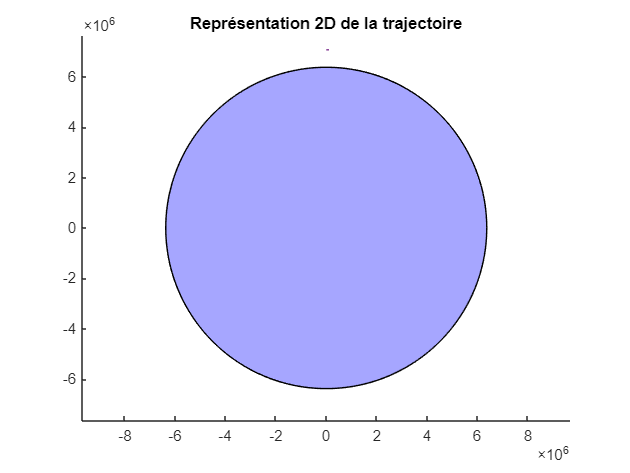

[xsphere,ysphere,zsphere] = sphere(20);
xterre=Rt*xsphere;
yterre=Rt*ysphere;
zterre=Rt*zsphere;

terre = nsidedpoly(1000, 'Radius', Rt);

figure
plot(terre,'FaceColor','b')
hold on
plot (x1.Data,y1.Data , x2.Data,y2.Data , x3.Data,y3.Data)
axis equal
title("Représentation 2D de la trajectoire")

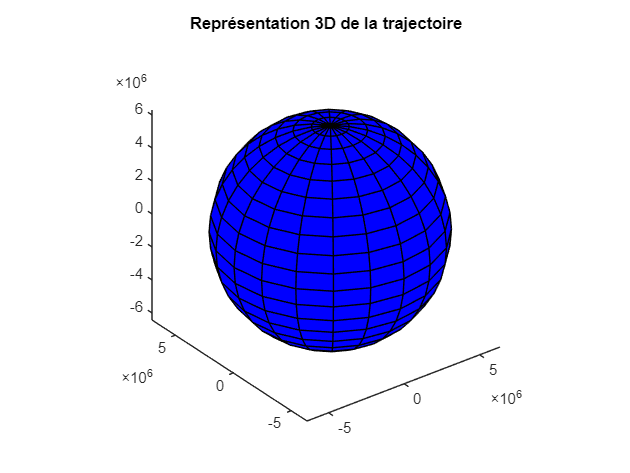


figure
plot3(x1.Data,y1.Data,z1.Data,x2.Data,y2.Data,z2.Data,x3.Data,y3.Data,z3.Data)
hold on
surf(xterre,yterre,zterre,'FaceColor','b')
axis equal
title("Représentation 3D de la trajectoire")

Vitesse minimal

disp("Vitesse minimale")

Vitesse minimale


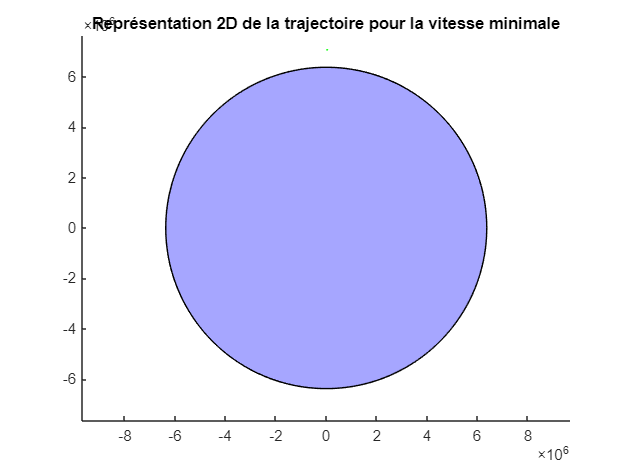

vmin=sqrt(G*Mt/(Rt+h0));

v0=vmin;
sim Sim_partie1.slx;
x=ans.x;
y=ans.y;
z=ans.z;

figure
plot(terre,'FaceColor','b')
hold on
plot (x.Data,y.Data,'g')
axis equal
title("Représentation 2D de la trajectoire pour la vitesse minimale")

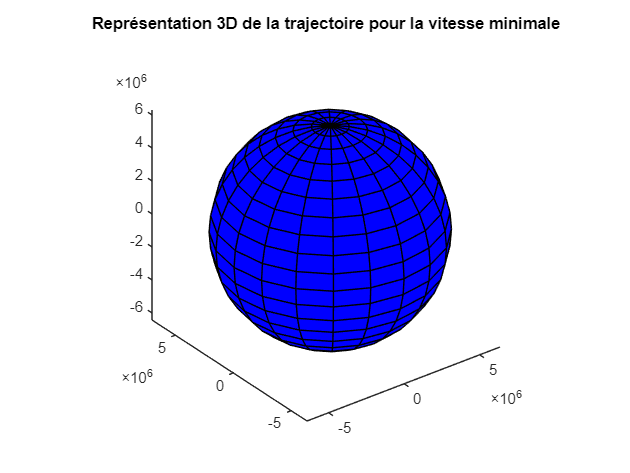


figure
plot3(x.Data,y.Data,z.Data,'g')
hold on
surf(xterre,yterre,zterre,'FaceColor','b')
axis equal
title("Représentation 3D de la trajectoire pour la vitesse minimale")

PARTIE 2

Première loi

disp("Première loi")

Première loi


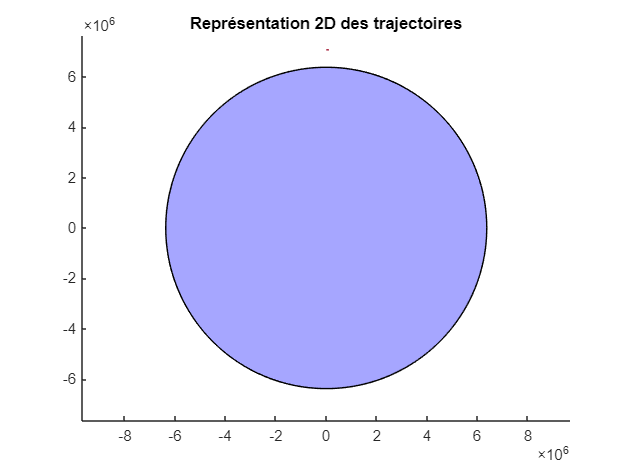

v0 = [vmin 7800 8400 9000 9600 10200];
sim Sim_partie1.slx;
x=ans.x;
y=ans.y;
z=ans.z;
r=ans.r;

figure
plot(terre,'FaceColor','b');
hold on
plot (x.Data,y.Data)
axis equal
title("Représentation 2D des trajectoires")

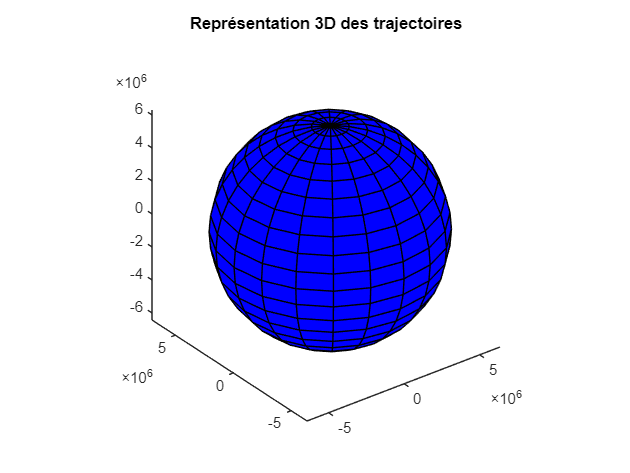


figure
plot3(x.Data,y.Data,z.Data)
hold on
surf(xterre,yterre,zterre,'FaceColor','b')
axis equal
title("Représentation 3D des trajectoires")

for i=1:6 %calcul de l'exentricite sous forme du vecteur pour chaque trajectoire
    ra=max(r.Data(:,i));
    rp=min(r.Data(:,i));
    e(i)=(ra-rp)/(ra+rp);
end
hold off


disp(e);

   1.0e-04 *

    0.0000    0.0221    0.0708    0.1231    0.1790    0.2385



Deuxieme loi

disp("Deuxieme loi")

Deuxieme loi


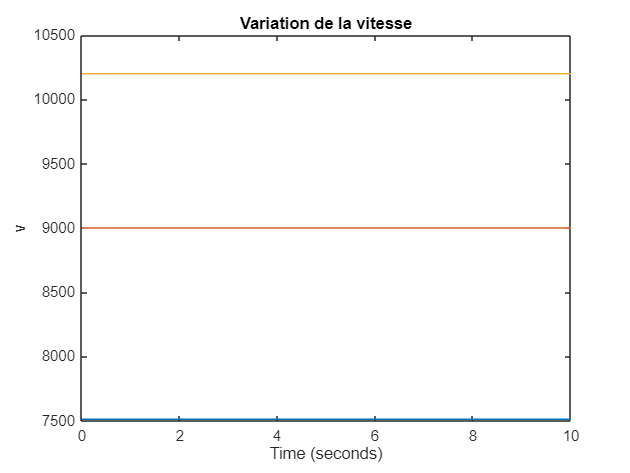

v0=[vmin 9000 10200];
sim Sim_partie1.slx;
r=ans.r;
v=ans.v;

figure
plot(v)
title("Variation de la vitesse")

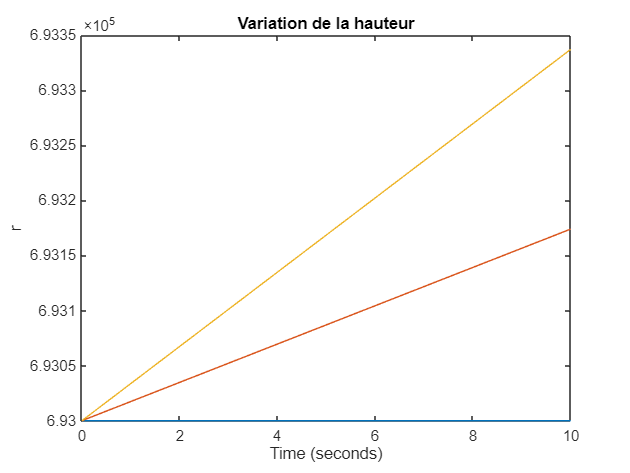


figure
plot(r-Rt)
title("Variation de la hauteur")

Troisieme loi

disp("Troisieme loi")

Troisieme loi


for i=1:3 %calcul du demi-grand axe sous forme du vecteur pour chaque trajectoire
    ra=max(r.Data(:,i));
    rp=min(r.Data(:,i));
    a=(ra+rp)/2;
    T=2*pi*(sqrt((a^3)/(G*(Mt+ms))));
    cst(i)=T^2/(a^3);
end
disp ("Les valeur de la constantes :")

Les valeur de la constantes :


disp(cst);

   1.0e-13 *

    0.9905    0.9905    0.9905



PARTIE 3

Sans pertutbation

disp("Calcul orbite sans perturbation")

Calcul orbite sans perturbation


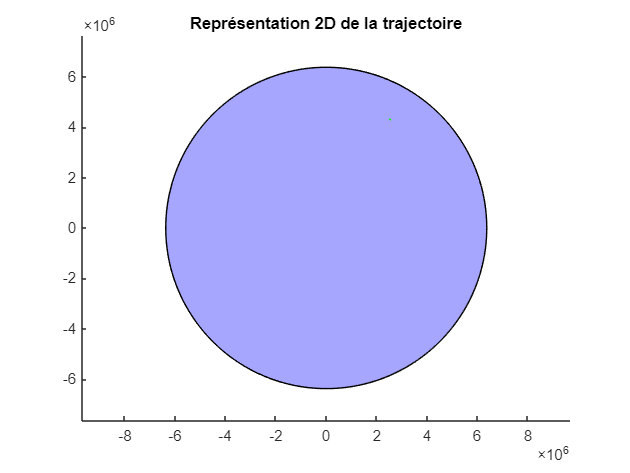

v0=9000;
theta=60;
phi=45;
r=Rt+h0;
sim Sim_partie1_bis;
x=ans.x.Data;
y=ans.y.Data;
z=ans.z.Data;
vx=ans.vx.Data;
vy=ans.vy.Data;
vz=ans.vz.Data;

figure
plot(terre,'FaceColor','b')
hold on
plot (x,y,'g')
axis equal
title("Représentation 2D de la trajectoire")

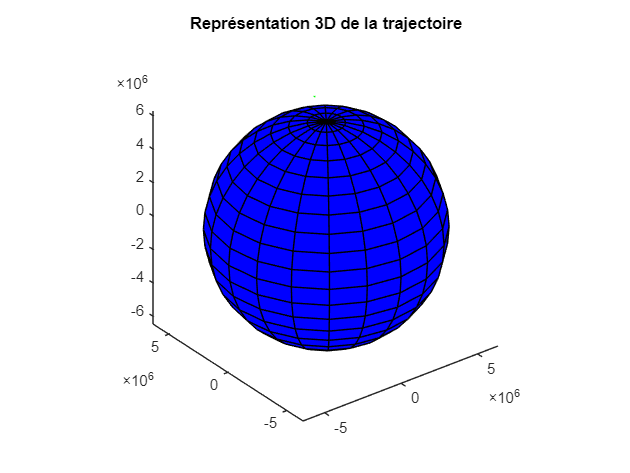


figure
plot3(x,y,z,'g')
hold on
surf(xterre,yterre,zterre,'FaceColor','b')
axis equal
title("Représentation 3D de la trajectoire")

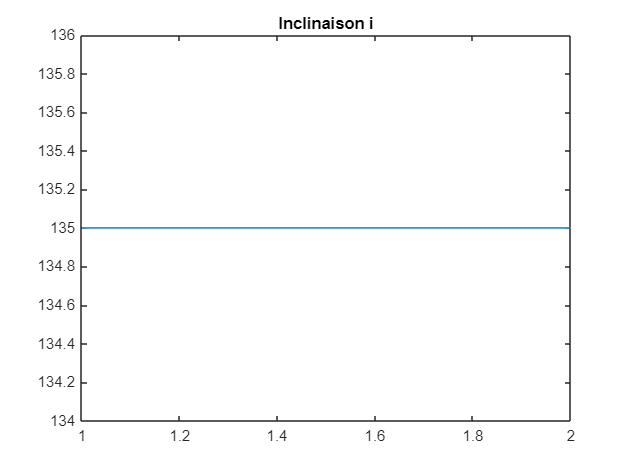


%calcul de i
hx = y.*vz - z.*vy;
hy = z.*vx - x.*vz;
hz = x.*vy - y.*vx;

i=acosd(hz./sqrt(hx.^2+hy.^2+hz.^2));
figure
plot(i)
title("Inclinaison i")

Prise en compte de J2 uniquement

disp("Calcul J2")

Calcul J2


%calcul du gradient
syms x y z J2 G Mt Rt
r=sqrt(x^2+y^2+z^2);
Ep=-G*Mt/r*(1-(J2*(Rt/r)^2*0.5*(3*(z/r)^2-1)));
grad_Ep=gradient(Ep,[x y z]);

% Compute simplified symbolic expression
simplifiedExpr = simplify(grad_Ep)

$$simplifiedExpr = \begin{array}{l} \left(\begin{array}{c} \frac{2\,G\,\mathrm{Mt}\,x\,{\sigma_{2}}^{2}-15\,G\,J_{2}\,\mathrm{Mt}\,{\mathrm{Rt}}^{2}\,x\,z^{2}+3\,G\,J_{2}\,\mathrm{Mt}\,{\mathrm{Rt}}^{2}\,x\,\sigma_{2}}{\sigma_{1}}\\ \frac{2\,G\,\mathrm{Mt}\,y\,{\sigma_{2}}^{2}-15\,G\,J_{2}\,\mathrm{Mt}\,{\mathrm{Rt}}^{2}\,y\,z^{2}+3\,G\,J_{2}\,\mathrm{Mt}\,{\mathrm{Rt}}^{2}\,y\,\sigma_{2}}{\sigma_{1}}\\ \frac{2\,G\,\mathrm{Mt}\,z\,{\sigma_{2}}^{2}-15\,G\,J_{2}\,\mathrm{Mt}\,{\mathrm{Rt}}^{2}\,z^{3}+9\,G\,J_{2}\,\mathrm{Mt}\,{\mathrm{Rt}}^{2}\,z\,\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,{\sigma_{2}}^{7/2}\\ \sigma_{2}=x^{2}+y^{2}+z^{2} \end{array}$$

Definition des constantes et affichage

G=6.6743*10^-11;
Mt=5.972*10^24;
Rt=6371000;
h0=693000;
r=Rt+h0;
J2 = 1.08263*10^(-3);

sim Sim_partie3.slx;
x=ans.x.Data;
y=ans.y.Data;
z=ans.z.Data;
vx=ans.vx.Data;
vy=ans.vy.Data;
vz=ans.vz.Data;
figure
plot(terre,'FaceColor','b')
hold on
plot (x,y,'g')
axis equal
title("Représentation 2D de la trajectoire")


figure
plot3(x,y,z,'g')
hold on
surf(xterre,yterre,zterre,'FaceColor','b')
axis equal
title("Représentation 3D de la trajectoire")

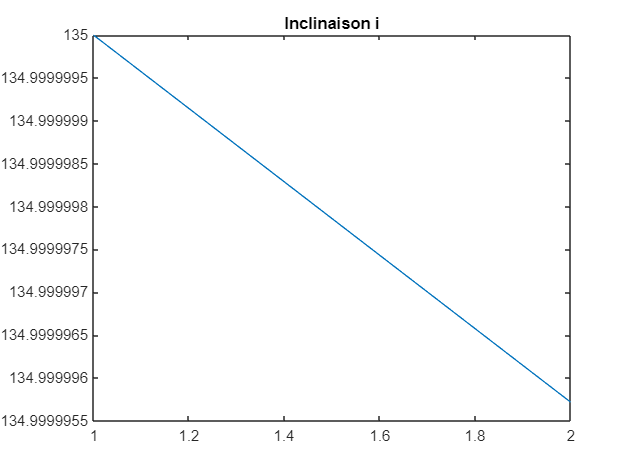


%calcul de l'inclinaison

hx = y.*vz - z.*vy;
hy = z.*vx - x.*vz;
hz = x.*vy - y.*vx;

i=acosd(hz./sqrt(hx.^2+hy.^2+hz.^2));
figure
plot(i)
title("Inclinaison i")

Prise en compte de J2 et de J3

disp("Calcul J2 et J3")

Calcul J2 et J3



syms x y z J2 J3 G Mt Rt
r=sqrt(x^2+y^2+z^2);
Ep=-G*Mt/r*(1-((J2*(Rt/r)^2*0.5*(3*(z/r)^2-1))+(J3*(Rt/r)^3*0.5*(5*(z/r)^3-3*(z/r)))));
grad_Ep=gradient(Ep,[x y z]);

% Compute simplified symbolic expression
simplifiedExpr2 = simplify(grad_Ep)

$$simplifiedExpr2 = \begin{array}{l} \left(\begin{array}{c} \frac{2\,G\,\mathrm{Mt}\,x\,{\sigma_{2}}^{3}-35\,G\,J_{3}\,\mathrm{Mt}\,{\mathrm{Rt}}^{3}\,x\,z^{3}+3\,G\,J_{2}\,\mathrm{Mt}\,{\mathrm{Rt}}^{2}\,x\,{\sigma_{2}}^{2}-15\,G\,J_{2}\,\mathrm{Mt}\,{\mathrm{Rt}}^{2}\,x\,z^{2}\,\sigma_{2}+15\,G\,J_{3}\,\mathrm{Mt}\,{\mathrm{Rt}}^{3}\,x\,z\,\sigma_{2}}{\sigma_{1}}\\ \frac{2\,G\,\mathrm{Mt}\,y\,{\sigma_{2}}^{3}-35\,G\,J_{3}\,\mathrm{Mt}\,{\mathrm{Rt}}^{3}\,y\,z^{3}+3\,G\,J_{2}\,\mathrm{Mt}\,{\mathrm{Rt}}^{2}\,y\,{\sigma_{2}}^{2}-15\,G\,J_{2}\,\mathrm{Mt}\,{\mathrm{Rt}}^{2}\,y\,z^{2}\,\sigma_{2}+15\,G\,J_{3}\,\mathrm{Mt}\,{\mathrm{Rt}}^{3}\,y\,z\,\sigma_{2}}{\sigma_{1}}\\ \frac{2\,G\,\mathrm{Mt}\,z\,{\sigma_{2}}^{3}-3\,G\,J_{3}\,\mathrm{Mt}\,{\mathrm{Rt}}^{3}\,{\sigma_{2}}^{2}-35\,G\,J_{3}\,\mathrm{Mt}\,{\mathrm{Rt}}^{3}\,z^{4}+9\,G\,J_{2}\,\mathrm{Mt}\,{\mathrm{Rt}}^{2}\,z\,{\sigma_{2}}^{2}-15\,G\,J_{2}\,\mathrm{Mt}\,{\mathrm{Rt}}^{2}\,z^{3}\,\sigma_{2}+30\,G\,J_{3}\,\mathrm{Mt}\,{\mathrm{Rt}}^{3}\,z^{2}\,\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,{\sigma_{2}}^{9/2}\\ \sigma_{2}=x^{2}+y^{2}+z^{2} \end{array}$$


%definition des constantes
G=6.6743*10^-11;
Mt=5.972*10^24;
Rt=6371000;
h0=693000;
r=Rt+h0;
J2 = 1.08263*10^(-3);
J3 = -2.532*10^(-6);
sim Sim_partie3_J2_J3.slx;
x=ans.x.Data;
y=ans.y.Data;
z=ans.z.Data;
vx=ans.vx.Data;
vy=ans.vy.Data;
vz=ans.vz.Data;

figure
plot(terre,'FaceColor','b')
hold on
plot (x,y,'g')
axis equal
title("Représentation 2D de la trajectoire")


figure
plot3(x,y,z,'g')
hold on
surf(xterre,yterre,zterre,'FaceColor','b')
axis equal
title("Représentation 3D de la trajectoire")

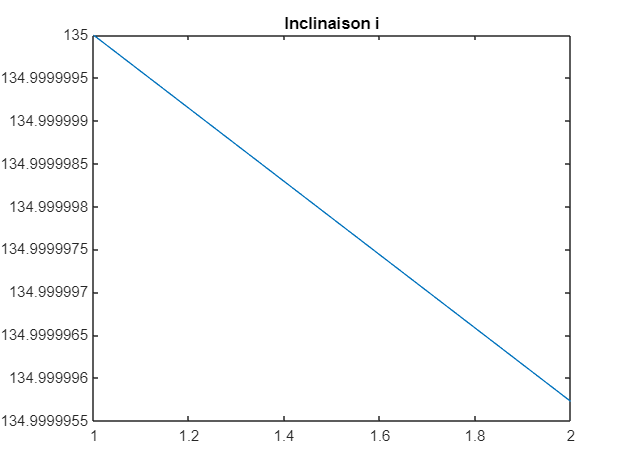


%calcul de l'inclinaison

hx = y.*vz - z.*vy;
hy = z.*vx - x.*vz;
hz = x.*vy - y.*vx;

i=acosd(hz./sqrt(hx.^2+hy.^2+hz.^2));
figure
plot(i)
title("Inclinaison i")